clear
close all
%---setting
expri='ens02';   member=1:10;    lev=1:17;  
%year='2007'; mon='06'; date='01';
year='2018'; mon='06'; date='22';  hr=1:5;  minu='00';
dirmem='pert'; infilenam='wrfout';  dom='01';

indir=['E:/wrfout/expri_ens200323/',expri];
outdir='E:/figures/expri191009/';
titnam='KE spectral';   fignam=[expri,'_KE-sptrl_'];

tic
%dx=1000; dy=1000;

nti=0;    
for ti=hr
  nti=nti+1;
  nmi=0;
  s_hr=num2str(ti,'%.2d');  % start time string
  % ensemble mean
  infile=[indir,'/mean/wrfmean_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
    u.stag = ncread(infile,'U');u.stag=double(u.stag);
    v.stag = ncread(infile,'V');v.stag=double(v.stag);
    %---
    u.mean=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
    v.mean=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;
    
  for mi=member
    nmi=nmi+1;
    %---set filename---
    nen=num2str(mi,'%.2d');
    infile=[indir,'/',dirmem,nen,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
    %------read netcdf data--------
    u.stag = ncread(infile,'U');u.stag=double(u.stag);
    v.stag = ncread(infile,'V');v.stag=double(v.stag);
    %---
    u.unstag=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
    v.unstag=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;
    u.pert=u.unstag - u.mean;
    v.pert=v.unstag - v.mean;
    
    %---start calculating---
    if nti==1 && nmi==1
      [nx, ny, ~]=size(u.unstag); 
      %Lx=dx*nx;  Ly=dy*ny;
      cenx=ceil((nx+1)/2);  ceny=ceil((ny+1)/2);
      nk=zeros(nx,ny);
      for xi=1:nx
      for yi=1:ny
        nk(xi,yi)=((xi-cenx)^2+(yi-ceny)^2)^0.5;        
      end    
      end   
      nk2=round(nk);  %!! 算好一個nk矩陣，直接四捨五入! 
      
      KE_khm=zeros(max(max(nk2)),length(hr));   %KE_kh of different time
      KE_pert_khm=zeros(max(max(nk2)),length(hr));
    end
  
    %---2D fft for different levels
    KE=zeros(nx,ny);  
    KE_pert=zeros(nx,ny); 
    for lvi=lev
      u.fft=fft2(u.unstag(:,:,lvi));
      v.fft=fft2(v.unstag(:,:,lvi));
      u.perfft=fft2(u.pert(:,:,lvi));
      v.perfft=fft2(v.pert(:,:,lvi));      
      %---calculate KE (power of the FFT)---
      KE(:,:)=KE(:,:)+( abs(u.fft)+abs(v.fft) )/length(lev);  %2-D low level mean
      KEshi=fftshift(KE);
      KE_pert(:,:)=KE_pert(:,:)+(abs(u.perfft)+abs(v.perfft))/length(lev);
      KE_pertshi=fftshift(KE_pert);
    end
    %----
    if nmi==1
      KE_kh=zeros(max(max(nk2)),length(member));  % KE_Kh of each member, reset to zero for each time step
      KE_pert_kh=zeros(max(max(nk2)),length(member));
    end
    for ki=1:max(max(nk2))   
      KE_kh(ki,mi)=sum(KEshi(nk2==ki));   % sum of different kx, ky to kh bin, for each member
      KE_pert_kh(ki,mi)=sum(KE_pertshi(nk2==ki));
    end
  end  %member
  KE_khm(:,nti)=mean(KE_kh,2);   %ensemble mean
  KE_pert_khm(:,nti)=mean(KE_pert_kh,2);
end  %ti
toc

経過時間は 13.916943 秒です。


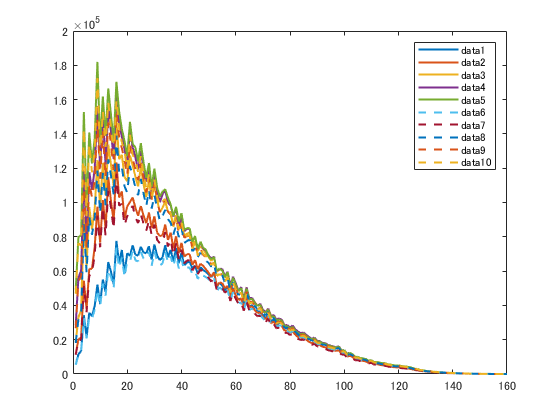

figure 
plot(KE_khm,'LineWidth',1.5); hold on
plot(KE_pert_khm,'LineWidth',1.5,'LineStyle','--')
legend